# **Data wrangling**

First we will load the data from the csv file and store the values in a table. After reading the data we  can look at a brief summary of the contents of the table using the command summary

read_example_data;
summary(subjectdata);


Variables:

    size: 14400×1 double

        Values:

            Min       1     
            Median    2     
            Max       4     

    condition: 14400×1 categorical

        Values:

            easy    7200       
            hard    7200       

    trial: 14400×1 double

        Values:

            Min           1  
            Median    120.5  
            Max         240  

    subject: 14400×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    correct: 14400×1 double

        Values:

            Min       0        
            Median    1        
            Max       1        

    RT: 14400×1 double

        Values:

            Min       24.915
            Median    213.15
            Max         1143



We can use functions on specific attributes of the subjectdata table to extract any particular quantity of interest we may need. For eg: the average proportion of correct responses across subjects which is the mean of the correct attribute

meanCorrect=mean(subjectdata.correct);
disp(['Average proportion of correct responses across subjects: ',num2str(meanCorrect)])

Average proportion of correct responses across subjects: 0.60681


We can also view conditional summaries, i.e. summary for a particular class of subjects or task categories. For eg: If we wanted the average proportion of correct responses if just for the stimuli of size 1, we can compute that by just computing the mean of responses where the size is 1.

meanCorrect_sz1=mean(subjectdata.correct(subjectdata.size==1));
disp(['Average proportion of correct responses across subjects for stimulus size 1: ',num2str(meanCorrect_sz1)])

Average proportion of correct responses across subjects for stimulus size 1: 0.50229


If we get new attributes which we want to append to a matlab table using a common attribute, we can use the command join. For eg. if we get the gender and age of the subjects tagged by their subject ID, we can use the join command to combine the information between the two tables.

table_new=[];
table_new.subject=[1:10]';
table_new.gender=categorical({'Female';'Male';'Male';'Female';'Female';'Male';'Female';'Male';'Female';'Male'});
table_new.age=[20;19;22;19;19;21;20;21;19;20];
table_new=struct2table(table_new);
summary(table_new);


Variables:

    subject: 10×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    gender: 10×1 categorical

        Values:

            Female    5       
            Male      5       

    age: 10×1 double

        Values:

            Min       19   
            Median    20   
            Max       22   




subjectdata=join(subjectdata,table_new);
summary(subjectdata);


Variables:

    size: 14400×1 double

        Values:

            Min       1     
            Median    2     
            Max       4     

    condition: 14400×1 categorical

        Values:

            easy    7200       
            hard    7200       

    trial: 14400×1 double

        Values:

            Min           1  
            Median    120.5  
            Max         240  

    subject: 14400×1 double

        Values:

            Min         1      
            Median    5.5      
            Max        10      

    correct: 14400×1 double

        Values:

            Min       0        
            Median    1        
            Max       1        

    RT: 14400×1 double

        Values:

            Min       24.915
            Median    213.15
            Max         1143

    gender: 14400×1 categorical

        Values:

            Female 

# Data visualization

If we want to visualize certain attributes of the data, we can do that using the plot command. Let's say we want to plot the reaction times as a function of size for subject 1

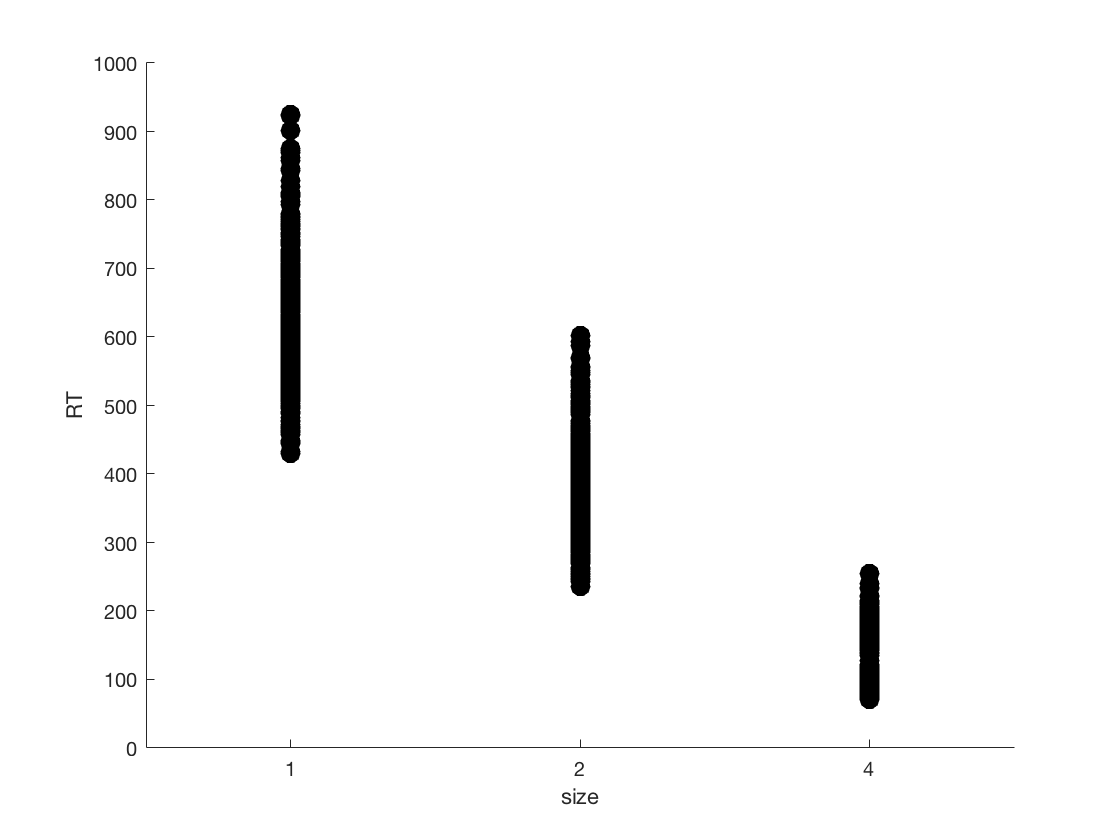

ids_plot=subjectdata.subject==1;
scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT(ids_plot),100,'k','filled');
xlabel('size');
ylabel('RT');

Notice that this plot is not particularly helpful! There is a lot of points and they are all overlaid, making it hard to get a clear idea of the data. One way we can improve this plot is to add transparency to the points. Another way is to jitter the points along the x-axis. Both approaches help convey information about the distribution of RTs at each number size, and sometimes—especially, when we have a lot of data—we might want to combine both approaches. For example, here’s the same plot with just transparency added. Since we have quite a bit of data, it still does not convey much information: 

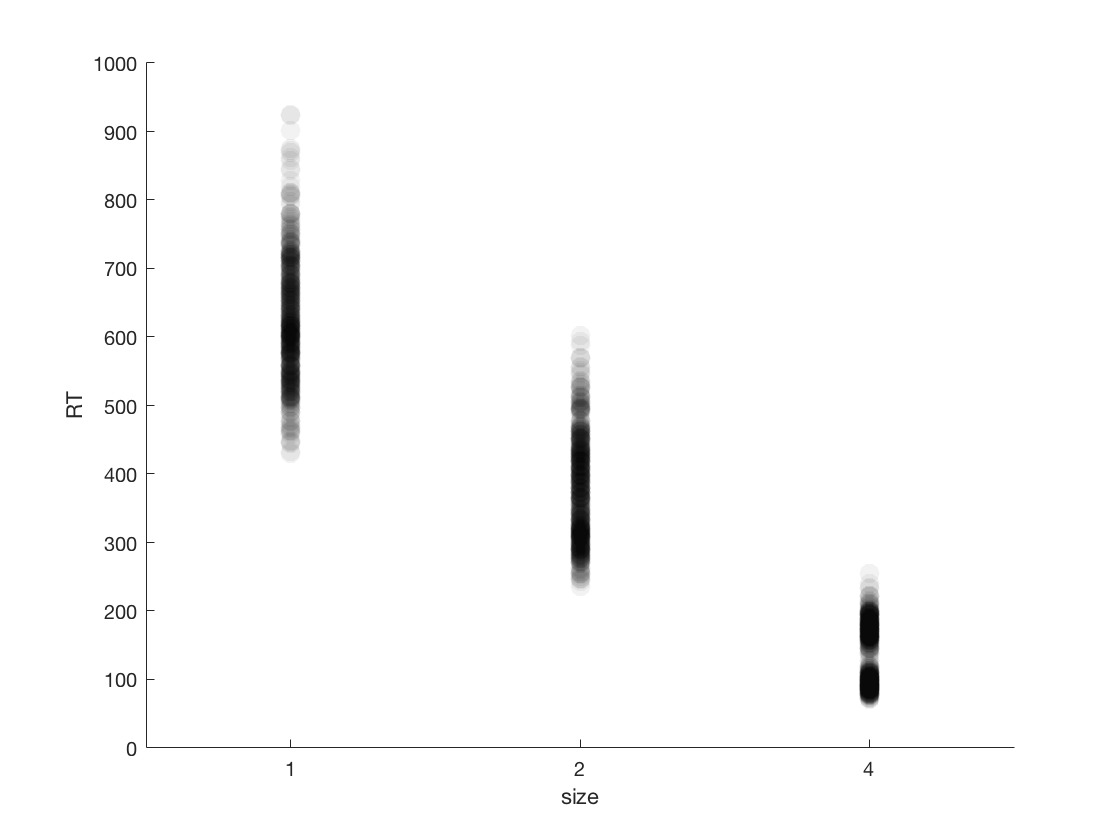

scatter1=scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT((ids_plot)),100,'k','filled');
alpha(scatter1,0.05)
xlabel('size');
ylabel('RT');

And here is the plot with some additional jitter added along the x-axis. Note that we intentionally avoid jitter along the y-axis: (why?)

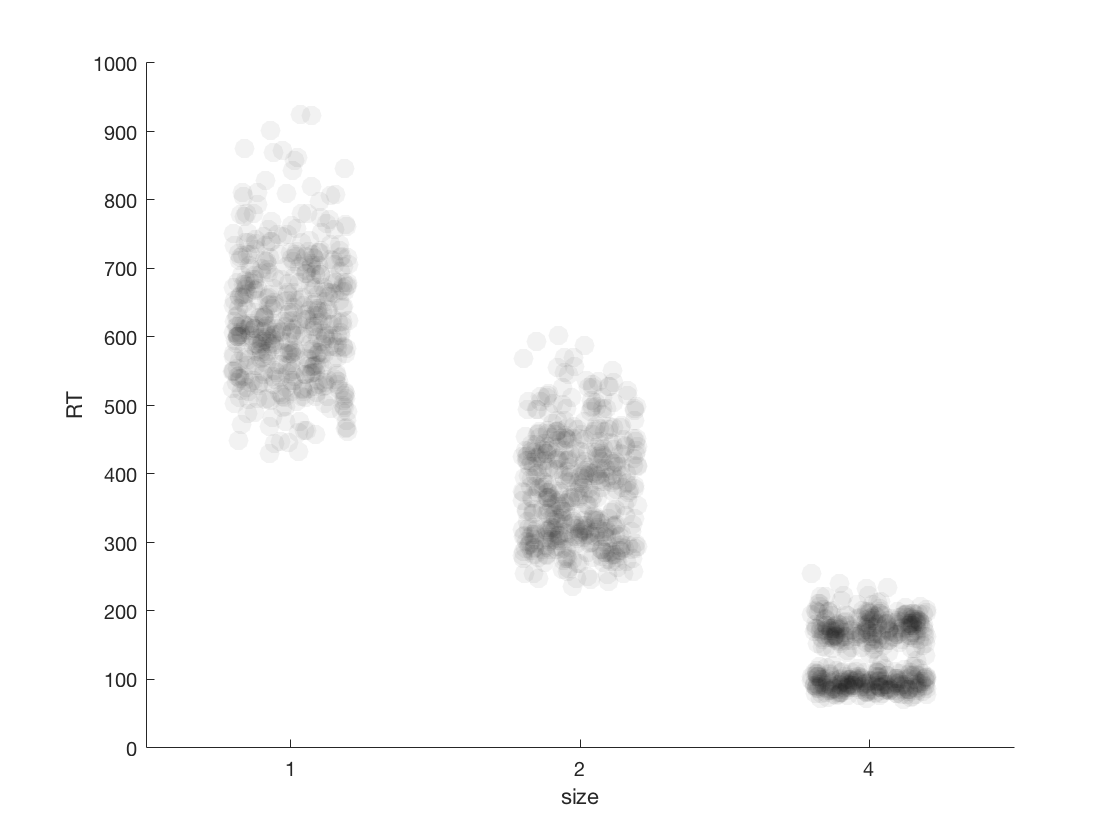

scatter1=scatter(categorical(subjectdata.size(ids_plot)),subjectdata.RT((ids_plot)),100,'k','filled','jitter','on','jitteramount',0.2);
alpha(scatter1,0.05)
xlabel('size');
ylabel('RT');

That’s much better already, giving us a much clearer idea of how the data is distributed! We are now in a position to think about how to include information about condition in this plot. There are a few ways to do this. For example, we could use di erent point shapes or colors for the easy and hard condition. Here, we do the latter: 

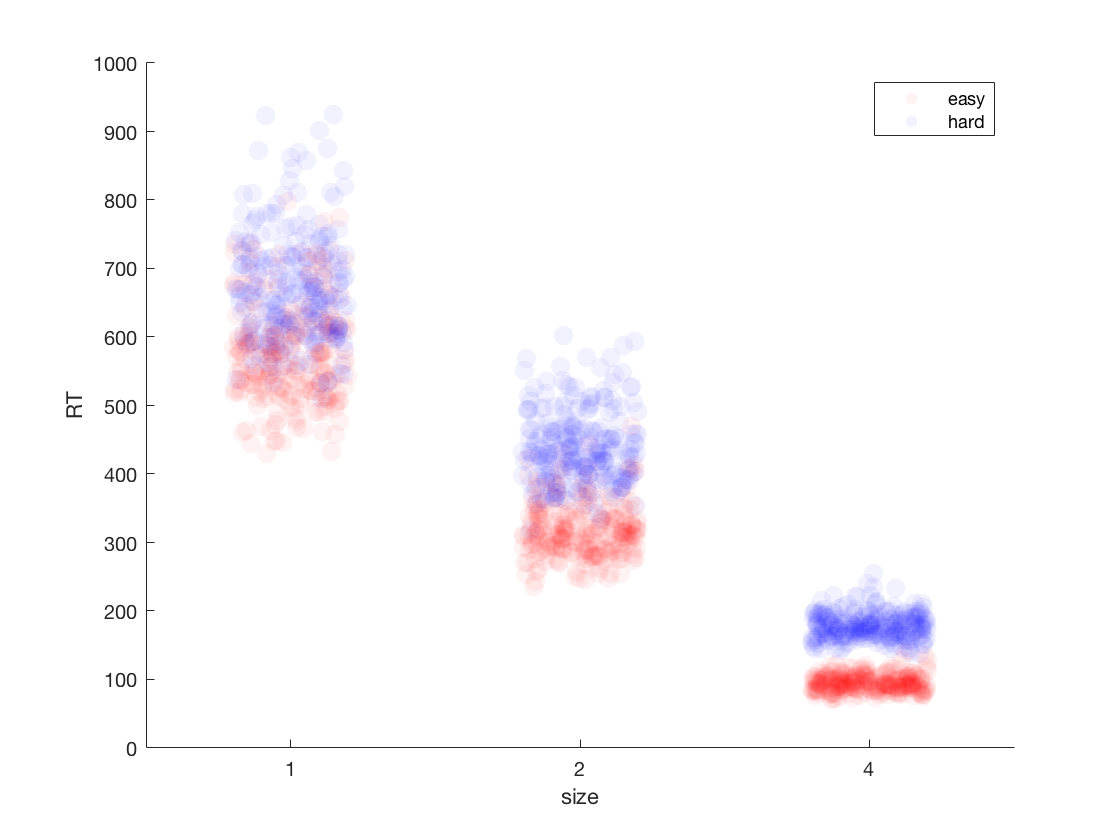

ids_plot_easy=(subjectdata.subject==1) & (subjectdata.condition=='easy');
ids_plot_hard=(subjectdata.subject==1) & (subjectdata.condition=='hard');

scatter1=scatter(categorical(subjectdata.size(ids_plot_easy)),subjectdata.RT((ids_plot_easy)),100,'r','filled','jitter','on','jitteramount',0.2);
hold on
scatter2=scatter(categorical(subjectdata.size(ids_plot_hard)),subjectdata.RT((ids_plot_hard)),100,'b','filled','jitter','on','jitteramount',0.2);

alpha(scatter1,0.05)
alpha(scatter2,0.05)
xlabel('size');
ylabel('RT');
legend({'easy','hard'});

While it is often useful to see the raw data, this alone can be insu cient to communicate important aspects of the data. Speci cally, we often are interested in whether the distributions of two conditions (e.g., the number size and easy vs. hard conditions) differ. The plots we have seen so far suggest that this might be the case, but we can’t be certain. In order to convey information about the distribution of our data, we often provide data summaries instead of—or in addition to—the raw data. Whenever possible, I would highly recommend to go with the “in addition to” option. There is a lof of value in seeing the raw data, as long as the overall tendencies we are interested in can also be recognized. 

Data can be summarized down to various levels of abstraction. For example, we can bin the data, and report the binned ‘raw’ data: 